clc;
clear;

## الف: تعریف سیگنال پیوسته

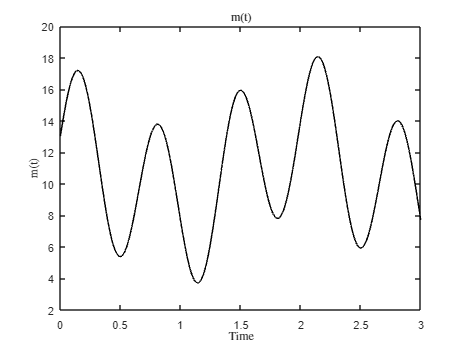

N = 50000;
t = linspace(0, 3, N); 
m = 10 +5.*sin(3*pi*t) + 3*cos(pi.*t).^3 + sin(pi.*t/4); 
plot(t, m,'k');
xlabel('Time','Interpreter','latex');
ylabel('m(t)','Interpreter','latex');
title('m(t)','Interpreter','latex');

## ب : نمونه برداری و تولید سیگنال گسسته

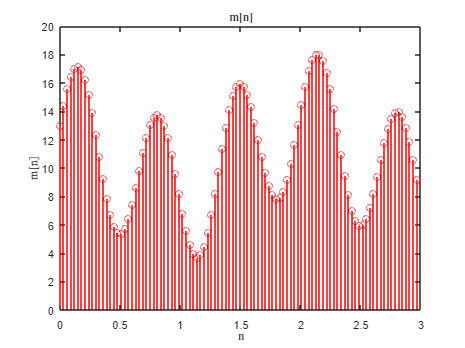

fs = 500;
ts = 1/fs;
t_sampled= downsample(t, fs);
m_sampled = downsample(m, fs);
stem(t_sampled, m_sampled,'Color','red');
xlabel('n','Interpreter','latex');
ylabel('m[n]', 'Interpreter','latex');
title('m[n]','Interpreter','latex');

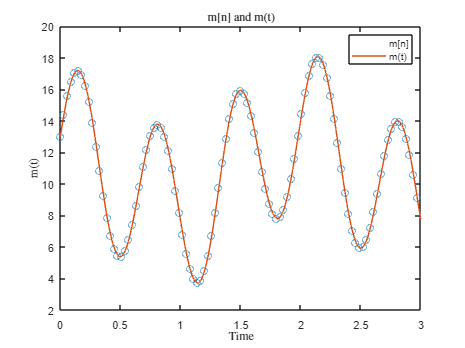

%..............................................%

plot(t_sampled,m_sampled,'o',t,m);
xlabel('Time','Interpreter','latex');
ylabel('m(t)', 'Interpreter','latex');
title('m[n] and m(t)','Interpreter','latex');
legend('m[n]','m(t)')

## ج: کوانتیزاسیون

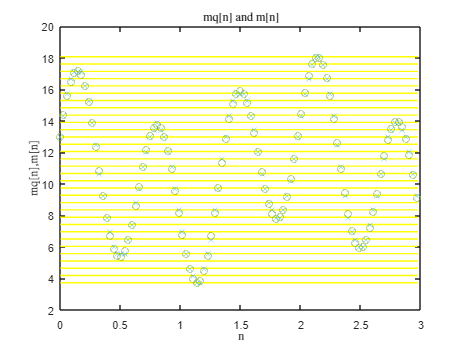

quant_levels = 32;
quant_step = (max(m_sampled) + 0.5  -  min(m_sampled)) / quant_levels;
partition = min(m_sampled) + quant_step/2: quant_step : max(m_sampled) + quant_step/2;
codebook = min(m_sampled)  : quant_step : max(m_sampled) + quant_step ;
[index, quants] = quantiz(m_sampled, partition, codebook);
quant_level = ones(32,length(t_sampled));

for n = 0:31
    quant_level(n+1,:) = min(m_sampled) + (n)*quant_step;
end
for n = 1:32
    plot(t_sampled,quant_level(n,:),'y')
    hold on
end

plot(t_sampled,m_sampled,'O',t_sampled,quants,'x')
xlabel('n','Interpreter','latex');
ylabel('mq[n],m[n]','Interpreter','latex');
title('mq[n] and m[n]','Interpreter','latex');
hold off

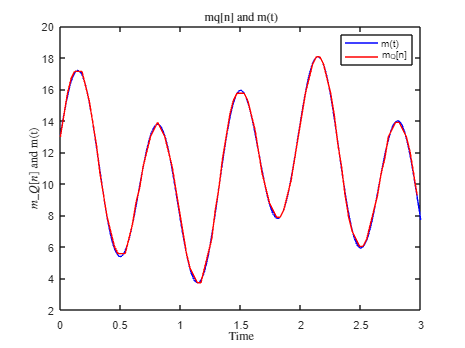

%..........................................................%

plot(t,m,'b',t_sampled,quants,'r')
xlabel('Time','Interpreter','latex')
ylabel('$m\_Q[n]$ and m(t)','Interpreter','latex')
title('mq[n] and m(t)','Interpreter','latex')
legend('m(t)', 'm_Q[n]')

## د: دیجیتال سازی سیگنال کوانتیزه شده

C(1,:) = {'00000','00001','00010','00011','00100','00101','00110','00111','01000','01001','01010','01011','01100','01101','01110','01111','10000','10001','10010','10011','10100','10101','10110','10111','11000','11001','11010','11011','11100','11101','11110','11111'}

C = 1×32 cell array
    {'00000'}    {'00001'}    {'00010'}    {'00011'}    {'00100'}    {'00101'}    {'00110'}    {'00111'}    {'01000'}    {'01001'}    {'01010'}    {'01011'}    {'01100'}    {'01101'}    {'01110'}    {'01111'}    {'10000'}    {'10001'}    {'10010'}    {'10011'}    {'10100'}    {'10101'}    {'10110'}    {'10111'}    {'11000'}    {'11001'}    {'11010'}    {'11011'}    {'11100'}    {'11101'}    {'11110'}    {'11111'}


C(2,:) = {-31,-29,-27,-25,-23,-21,-19,-17,-15,-13,-11,-9,-7,-5,-3,-1,1,3,5,7,9,11,13,15,17,19,21,23,25,27,29,31}

C = 2×32 cell array
    {'00000'}    {'00001'}    {'00010'}    {'00011'}    {'00100'}    {'00101'}    {'00110'}    {'00111'}    {'01000'}    {'01001'}    {'01010'}    {'01011'}    {'01100'}    {'01101'}    {'01110'}    {'01111'}    {'10000'}    {'10001'}    {'10010'}    {'10011'}    {'10100'}    {'10101'}    {'10110'}    {'10111'}    {'11000'}    {'11001'}    {'11010'}    {'11011'}    {'11100'}    {'11101'}    {'11110'}    {'11111'}
    {[  -31]}    {[  -29]}    {[  -27]}    {[  -25]}    {[  -23]}    {[  -21]}    {[  -19]}    {[  -17]}    {[  -15]}    {[  -13]}    {[  -11]}    {[   -9]}    {[   -7]}    {[   -5]}    {[   -3]}    {[   -1]}    {[    1]}    {[    3]}    {[    5]}    {[    7]}    {[    9]}    {[   11]}    {[   13]}    {[   15]}    {[   17]}    {[   19]}    {[   21]}    {[   23]}    {[   25]}    {[   27]}    {[   29]}    {[   31]}


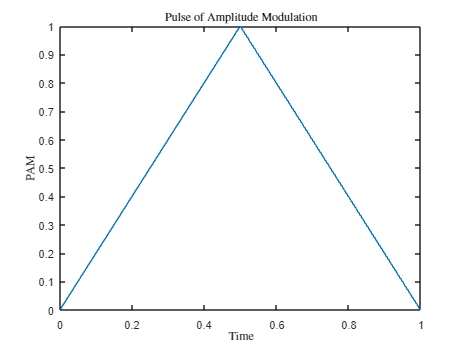

fs1 = 1000;
P = 'C:\Users\asus\OneDrive\Documents\term 5\Principles of communication  systems\CA3';
F = 'p.mat';  
data = load(fullfile(P,F));
p = cell2mat(struct2cell(data)); 
t1 = 0 :1/fs1:1-1/fs1;
plot(t1,p)
ylabel('PAM','Interpreter','latex')
xlabel('Time','Interpreter','latex')
title('Pulse of Amplitude Modulation','Interpreter','latex')

energy_p = mean(p.^2);
disp(['Energy of pulse is:', num2str(energy_p)]);

Energy of pulse is:0.33333


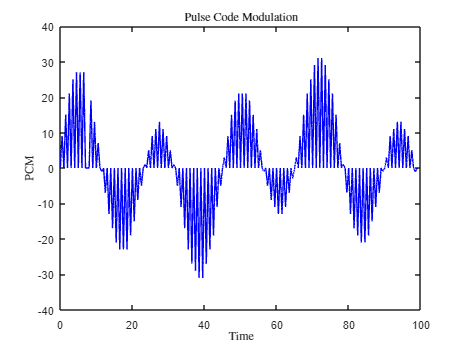

%....................................................%

gray_code = ['00000'; '00001'; '00011'; '00010'; '00110'; '00111'; '00101'; '00100'; '01100'; '01101'; '01111';
    '01110'; '01010'; '01011'; '01001'; '01000'; '11000'; '11001'; '11011'; '11010'; '11110'; '11111'; '11101';
    '11100'; '10100'; '10101'; '10111'; '10110'; '10010'; '10011'; '10001'; '10000'];
amplitude = cell2mat(C(2,:))';

quantized_gray_code = cell(length(quants), 1); % Initialize a cell array to store the quantized gray codes

for i = 1 : length(quants)
    for j = 1 : quant_levels
        if(quants(1,i) == quant_level(j,1))             
            quantized_gray_code{i} = num2str(gray_code(j,:), '%05d');
        end
    end
end

for i = 1 : length(quants)
    for j = 1 : quant_levels
        if strcmp(quantized_gray_code{i,1}, num2str(gray_code(j,:), '%05d'))
            modulated_signal(i,:) = p.*amplitude(j,1);
        end
    end
end

for i = 0 : 99
    t1(i+1,:) = i:0.001:i+1-0.001;
end 

for k = 1:99
    plot(t1(k,:),modulated_signal(k,:),'b')
    hold on 
end
ylabel('PCM','Interpreter','latex')
xlabel('Time','Interpreter','latex')
title('Pulse Code Modulation','Interpreter','latex')

## ه: دریافت سیگنال دیجیتال در گیرنده

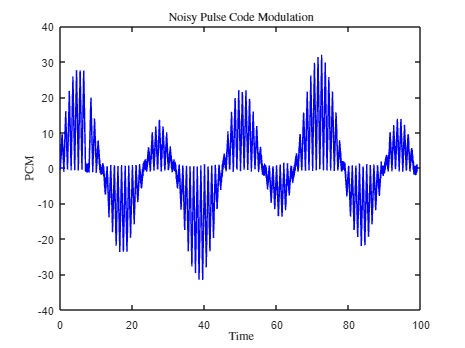

figure;
SNR = 10 ^0.2;
NR = energy_p / SNR;
noise = sqrt(NR) * randn(size(modulated_signal));
% normrnd(0, 1, size(modulated_signal));

received_signal = modulated_signal + noise;
for k = 1:99
    plot(t1(k,:),received_signal(k,:),'b')
    hold on 
end
ylabel('PCM','Interpreter','latex')
xlabel('Time','Interpreter','latex')
title('Noisy Pulse Code Modulation','Interpreter','latex')

## و: دیکود کردن سیگنال دیجیتال

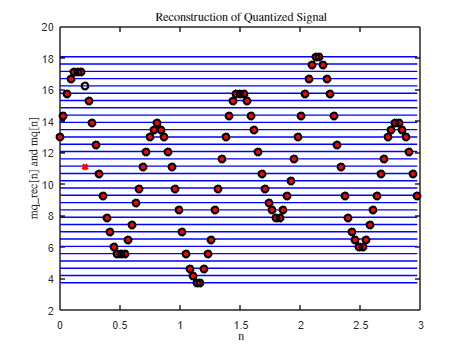

for  i = 1: 100
     demodulated_signal_amp (i,1)=  sum(received_signal(i,:).*p)/(1000*energy_p);
end
for i = 1:size(demodulated_signal_amp, 1)
    [~, index] = min(abs(demodulated_signal_amp(i, 1) - amplitude));
    nearest_digit(i,:) =  num2str(gray_code(index,:), '%05d');
end
for i = 1 : size(nearest_digit, 1)
      for j = 1 : quant_levels
        if strcmp( num2str(nearest_digit(i,:), '%05d'), num2str(gray_code(j,:), '%05d'))
        decoded_signal(i,:) = quant_level(j,1); 
        end
      end
end
figure;
for n = 1:32
    plot(t_sampled,quant_level(n,:),'b')
    hold on
end

plot(t_sampled,decoded_signal,'x','Color','r','LineWidth',3)
hold on 
plot(t_sampled,quants,'o','Color','k','LineWidth',2)
title('Reconstruction of Quantized Signal', 'Interpreter','latex')
xlabel('n','Interpreter','latex')
ylabel('mq\_rec[n] and mq[n]','Interpreter','latex')


%.......................................................%

num_different = sum(decoded_signal ~= quants');
error_percentage = num_different / 100 * 100;
disp(['Error: ', num2str(error_percentage),'%']);

Error: 1%


## ز: تبدیل سیگنال کوانتایی شده به آنالوگ و رسم دیاگرام

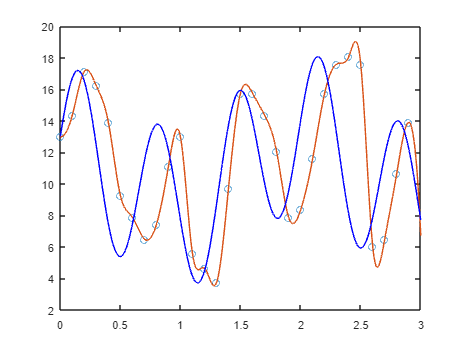


% for i = 1 : length(m_sampled)
%     if (m_sampled(1,i) == quants(1,i) )
%         x(1,i) = m_sampled(1,i)
%     end
% end

% for i = 1:length(m_sampled)
%     if (abs(m_sampled(i) - quants(i)) <= 0.01) 
%         x(i) = quants(i);
%     end
% end

x = [];
% z = zeros(size(m_sampled));

for i = 1:length(m_sampled)
    if abs(m_sampled(i) - quants(i)) <= 0.05
        x = [x, quants(i)];
%         z(i) = quants(i);
    end
end
% x = [0 1 2.5 3.6 5 7 8.1 10];
 
% y = 10 +5.*sin(3*pi*t) + 3*cos(pi.*t).^3 + sin(pi.*t/4); 
figure;
y = 0:0.1:3-0.1;
% y = 0:1/12:3-1/12;
% y = 0:0.5:3-0.5;
cs = spline(y,[0 x 0]);
xx = linspace(0, 3, N);
plot(y,x,'o',xx,ppval(cs,xx),'-');
hold on
plot(t,m,'b')
hold off


% error = m - ppval(cs,xx);
% 
% % Calculate MSE
% mse = mean(error.^2);
% 
% % Calculate RMSE
% rmse = sqrt(mse);
% 
% % Calculate MAE
% mae = mean(abs(error));
% 
% % Calculate PSNR
% maxValue = max(max(signal1), max(signal2));
% psnr = 20 * log10(maxValue) - 10 * log10(mse);
% xx = 0:.25:10;
% yy = spline(x,y,xx);
% plot(x,y,'o',xx,yy)

% for i = 1 : length(nearest_amplitude)
% %    num_different_bits = sum(cellfun(@(x, y) sum(x ~= y), num2cell(nearest_amplitude(i,:)), num2cell(quantized_gray_code(i,:))));
%     for k = 1:numel(nearest_amplitude(i,:))
%         str1 = num2str(nearest_amplitude(i,k), '%05d');
%         str2 = num2str(quantized_gray_code(j,k), '%05d');
%         num_different_bits = num_different_bits + sum(str1 ~= str2);
%     end
% end

% error = abs(decoded_signal - quants');
% num_different = sum(error(:) ~= 0); % Count the number of elements that are different
% error_percentage = num_different / (5*100) * 100 % Divide by the total number of samples and calculate the percentage
